### Sample data download

outputFolder = pwd;
dataURL = ['https://ssd.mathworks.com/supportfiles/radar/data/' ...
    'MSTAR_TargetData.tar.gz'];

% helperDownloadMSTARTargetData(outputFolder,dataURL);

### �

### Load dataset

sarDatasetPath = fullfile(pwd,'Data');
imds = imageDatastore(sarDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

### Shuffle dataset

rng(0)
imds = shuffle(imds);

### Get sample image from dataset

figure
for i = 1:20
    subplot(4,5,i)
    img = read(imds);
    imshow(img)
    title(imds.Labels(i))
    sgtitle('Sample training images')
end

figure
img = read(imds);
imshow(img)

### Data statistic

labelCount = countEachLabel(imds)

labelCount = 8×2 table
     Label      Count
    ________    _____

    2S1         1164 
    BRDM_2      1415 
    BTR_60       451 
    D7           573 
    SLICY       2539 
    T62          572 
    ZIL131       573 
    ZSU_23_4    1401 


### Set training configuration

imgSize = [128,128,1];

trainingPct = 0.8;
validationPct = 0.1;

### Split dataset (8:1:1)

[imdsTrain,imdsValidation,imdsTest] = splitEachLabel(imds,...
    trainingPct,validationPct,'randomize');

### Data augmentation (resize)

auimdsTrain = augmentedImageDatastore(imgSize, imdsTrain);
auimdsValidation = augmentedImageDatastore(imgSize, imdsValidation);
auimdsTest = augmentedImageDatastore(imgSize, imdsTest);

### Define network and hyper parameters

layers = createNetwork(imgSize);
options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.001, ...
    'MaxEpochs',3, ...
    'Shuffle','every-epoch', ...
    'MiniBatchSize',32,...  % 48 to 32
    'ValidationData',auimdsValidation, ...
    'ValidationFrequency',15, ...
    'Verbose',false, ...
    'CheckpointPath',tempdir,...
    'Plots','training-progress');

### Train

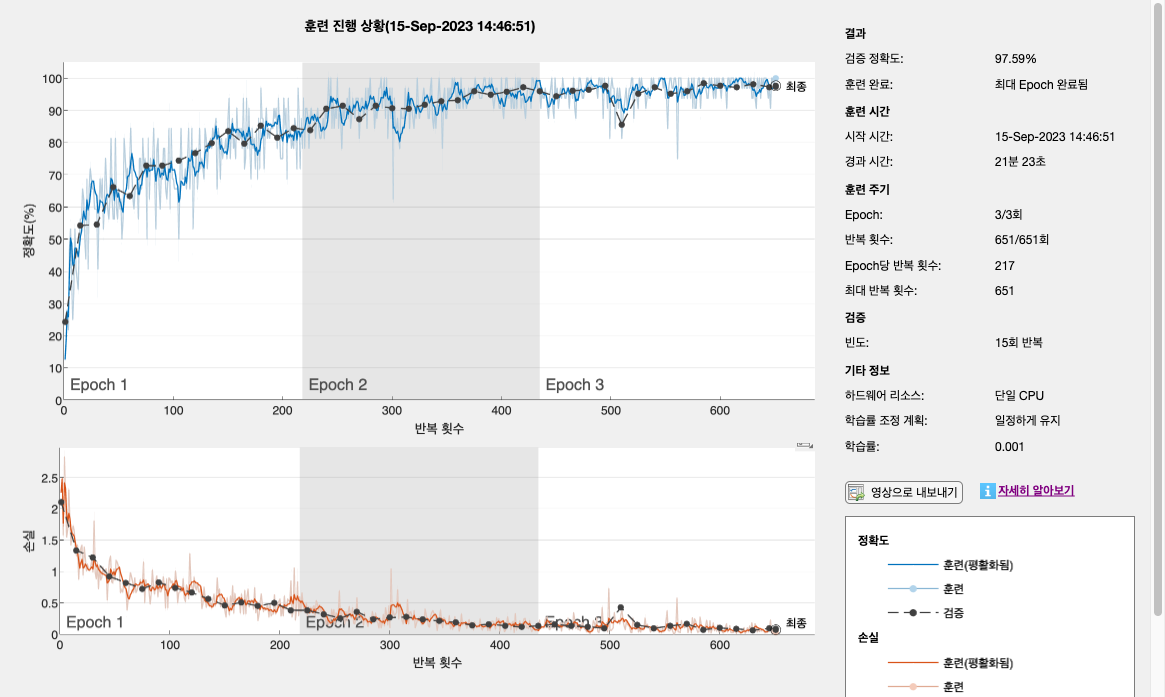

net =   SeriesNetwork - 속성 있음:

         Layers: [27×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


net = trainNetwork(auimdsTrain,layers,options)

### Test

YPred = classify(net,auimdsTest);
YTest = imdsTest.Labels;

accuracy = sum(YPred == YTest)/numel(YTest)

accuracy = 0.9862

### Visualize using Confusion matrix

figure
cm = confusionchart(YPred, YTest);
cm.RowSummary = 'row-normalized';
cm.Title = 'SAR Target Classification Confusion Matrix';

### �Define - download function

function helperDownloadMSTARTargetData(outputFolder,DataURL)
    radarDataTarFile = fullfile(outputFolder,'MSTAR_TargetData.tar.gz');
    
    if ~exist(radarDataTarFile,'file')
        
        disp('Downloading MSTAR Target data (28 MiB)...');
        websave(radarDataTarFile,DataURL);
        untar(radarDataTarFile,outputFolder);
    end
end

### Define - create network function

function layers = createNetwork(imgSize)
    layers = [
        imageInputLayer([imgSize(1) imgSize(2) 1])      % Input Layer
        convolution2dLayer(3,32,'Padding','same')       % Convolution Layer
        reluLayer                                       % Relu Layer
        convolution2dLayer(3,32,'Padding','same')
        batchNormalizationLayer                         % Batch normalization Layer
        reluLayer
        maxPooling2dLayer(2,'Stride',2)                 % Max Pooling Layer
        
        convolution2dLayer(3,64,'Padding','same')
        reluLayer
        convolution2dLayer(3,64,'Padding','same')
        batchNormalizationLayer
        reluLayer
        maxPooling2dLayer(2,'Stride',2)
        
        convolution2dLayer(3,128,'Padding','same')
        reluLayer
        convolution2dLayer(3,128,'Padding','same')
        batchNormalizationLayer
        reluLayer
        maxPooling2dLayer(2,'Stride',2)
    
        % SKIP 4TH block
        % convolution2dLayer(3,256,'Padding','same')
        % reluLayer
        % convolution2dLayer(3,256,'Padding','same')
        % batchNormalizationLayer
        % reluLayer
        % maxPooling2dLayer(2,'Stride',2)
    
        convolution2dLayer(6,256)       % output shape 512 to 256
        reluLayer
        
        dropoutLayer(0.5)
        fullyConnectedLayer(256)        % 512 to 256
        reluLayer
        fullyConnectedLayer(8)
        softmaxLayer
        classificationLayer
        ];
end